# clear environment

close all;
clear;
clc;
global debug;
global debug_che;
global debug_SingleDMRS;

debug=0;
debug_che=1;
debug_SingleDMRS=1;

mu=1;
conjugate=1;
f0=26550000;

tab_pc = phy_gnb_main_init_phase_compensation_table( f0,  mu, conjugate);

## full load data

dpath0='/Users/liqinghua/RF_data/D256QAM/';
upath0='/Users/liqinghua/RF_data/U64QAM/';
upath1='/Users/liqinghua/RF_data/UQPSK/';
upath0='/Users/liqinghua/log/phylog_20210311_0724_startP/data/';
upath0='/Users/liqinghua/log/phylog_20210311_0728_saturate/data/';
upath0='/Users/liqinghua/RF_data/phylog_20210218_0658_UL_90M_IQ/data/';
upath0='/Users/liqinghua/log/bug1138/data/';
upath0='/Users/liqinghua/RF_data/phylog_20210322_0730_80M_/data/';
upath0='/Users/liqinghua/RF_data/phylog_20210322_0728_170M_/data/';
upath0='/Users/liqinghua/RF_data/phylog_20210323_0849/data/';
upath0='Y:\256数据\phylog_20210323_0849\phylog_20210323_0849\data\';
upath0='\\172.21.6.6\oran\L1\liqh\256数据\phylog_20210323_0849\phylog_20210323_0849\data\';
upath0='~/oranliqh/256数据/phylog_20210323_0849/phylog_20210323_0849/data/';
upath0='~/oranliqh/256数据/256QAM_MCS27/phylog_20210323_0955/phylog_20210323_0955/data/';

ufile_ant0='FileUlLog_Instance0_Ant0.bin';
ufile_ant1='FileUlLog_Instance0_Ant1.bin';
dfile_ant0='FileDlLog_Instance0_Ant0.bin';
dfile_ant1='FileDlLog_Instance0_Ant1.bin';

ufile_ant0='iq_ul_ant0_car0.bin';
ufile_ant1='iq_ul_ant1_car0.bin';

ufile_ant0='FileUlLog_Instance0_Ant0.bin';
ufile_ant1='FileUlLog_Instance0_Ant1.bin';

%ufile_ant0='FileUlLog_Instance0_Ant1_slot9.bin';

%FILENAME=DFILE;
filename_ant0=ufile_ant0;
filename_ant1=ufile_ant1;
dirpath=upath0;

%Ant0=sprintf('%s%s',path,'FileUlLog_Instance0_Ant0.bin');
Ant0=[dirpath,filename_ant0];
Ant1=[dirpath,filename_ant1];
fprintf('Ant file: %s\n',Ant0);

Ant file: ~/oranliqh/256数据/256QAM_MCS27/phylog_20210323_0955/phylog_20210323_0955/data/FileUlLog_Instance0_Ant0.bin



v_slot=9;
ant=0;
Ant0_IQ=readAnt(Ant0,tab_pc);

        9216



Ant1_IQ=readAnt(Ant1,tab_pc);

   944



## start channel estimation

i=3;
fprintf("channel estimation with DMRS with slot %d & %d symbol \n",v_slot,i);

channel estimation with DMRS with slot 9 & 3 symbol 


Decode port 1001 DMRS


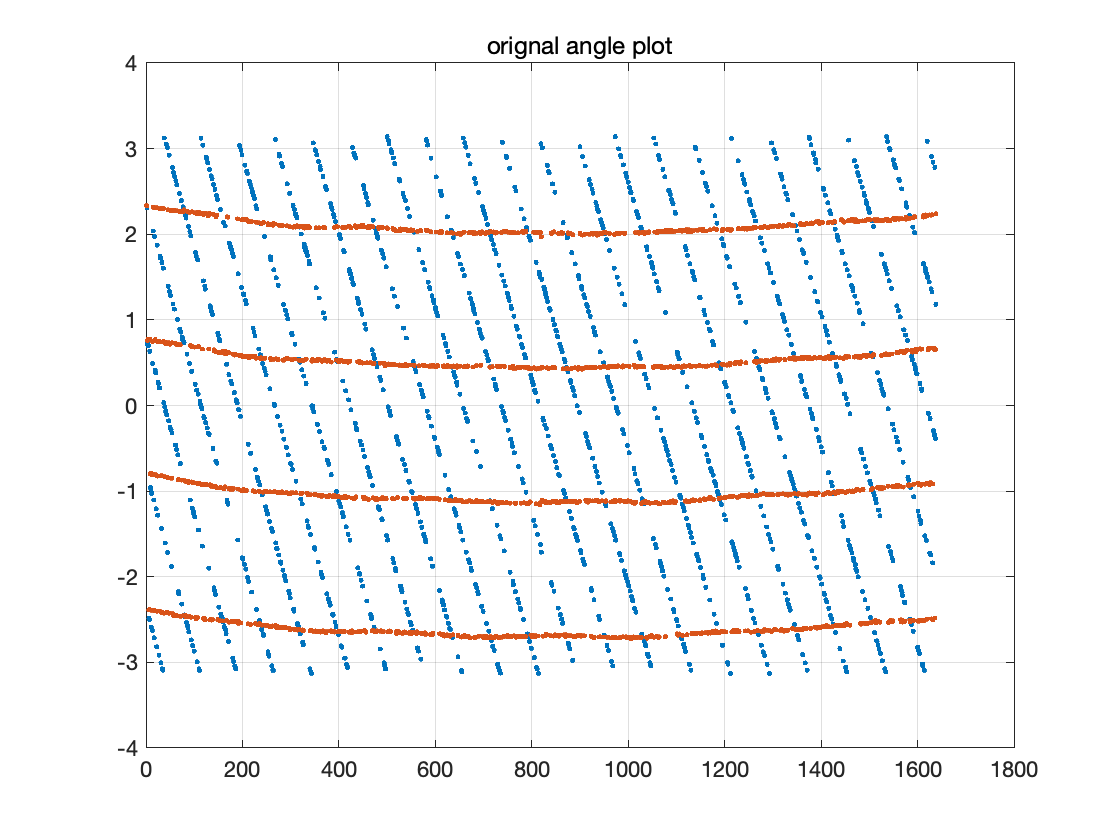

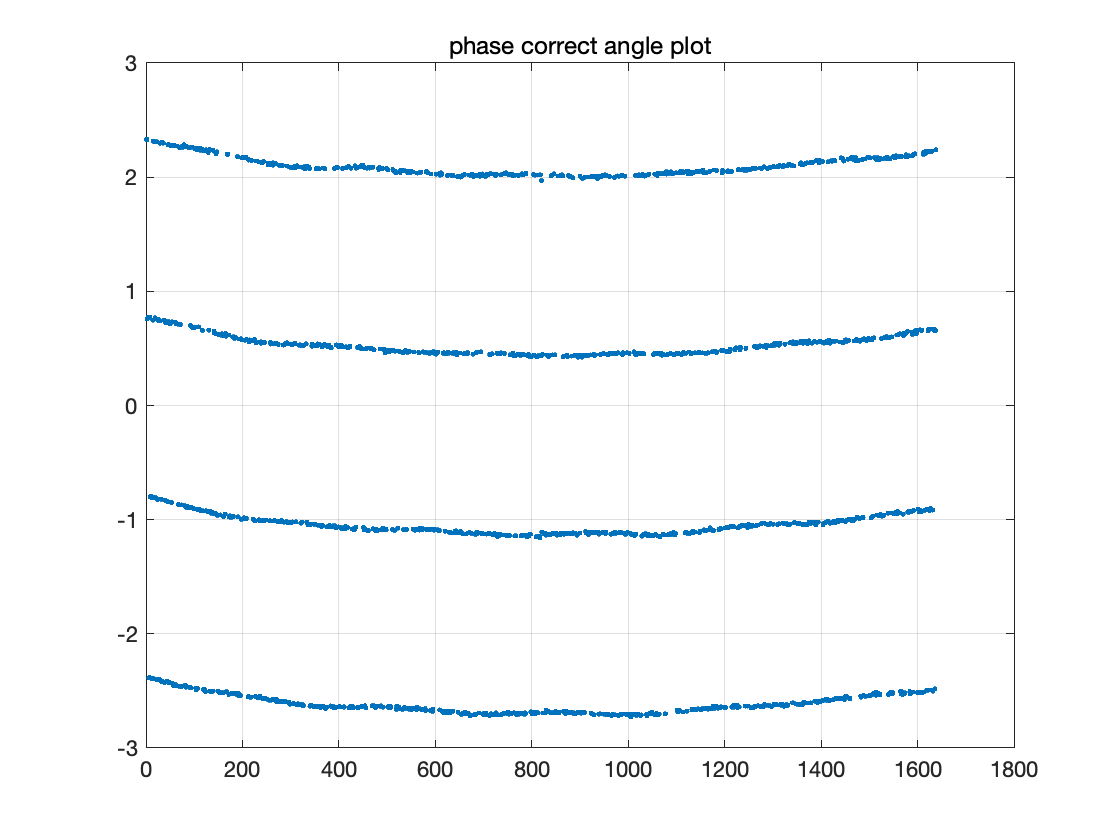

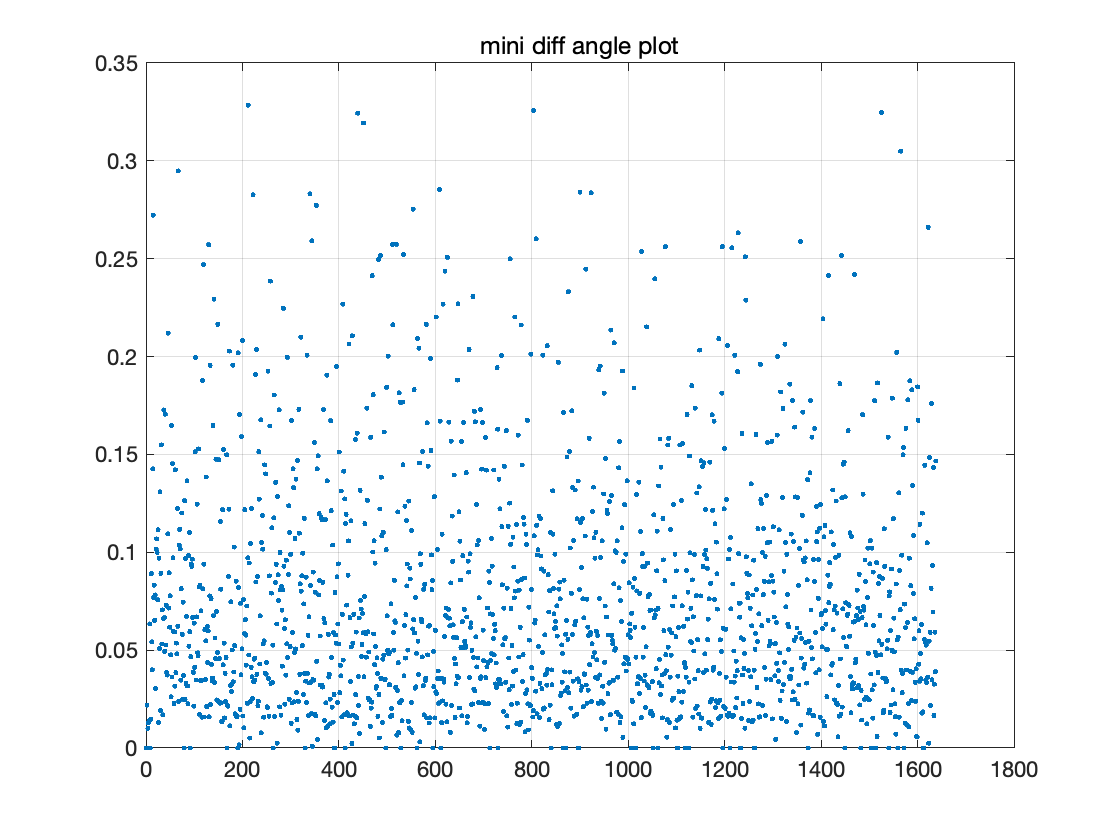

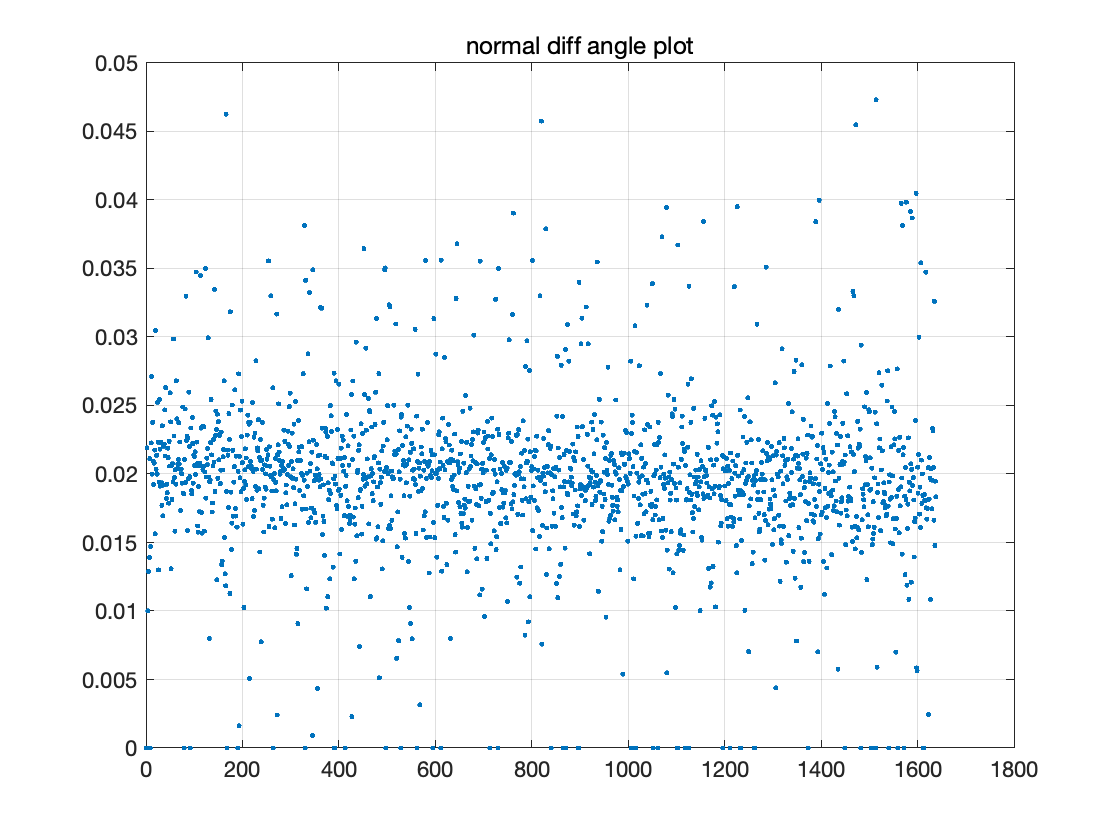

Decode port 1003 DMRS


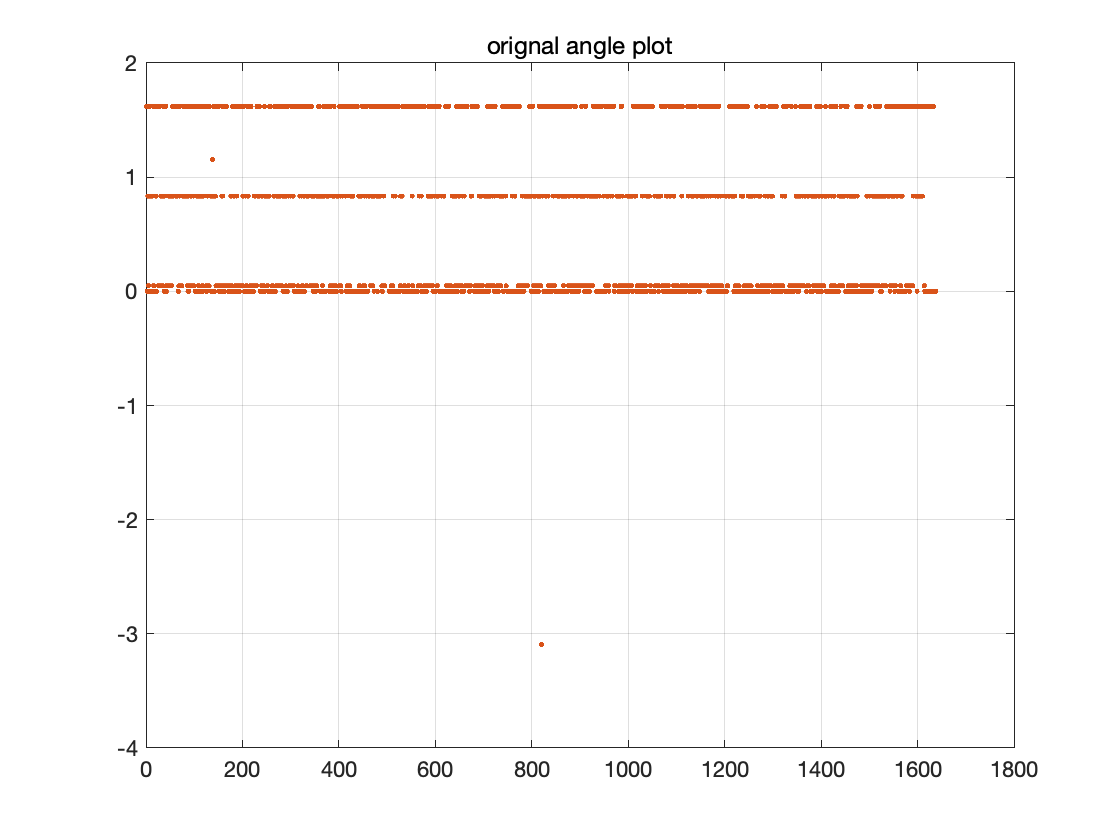

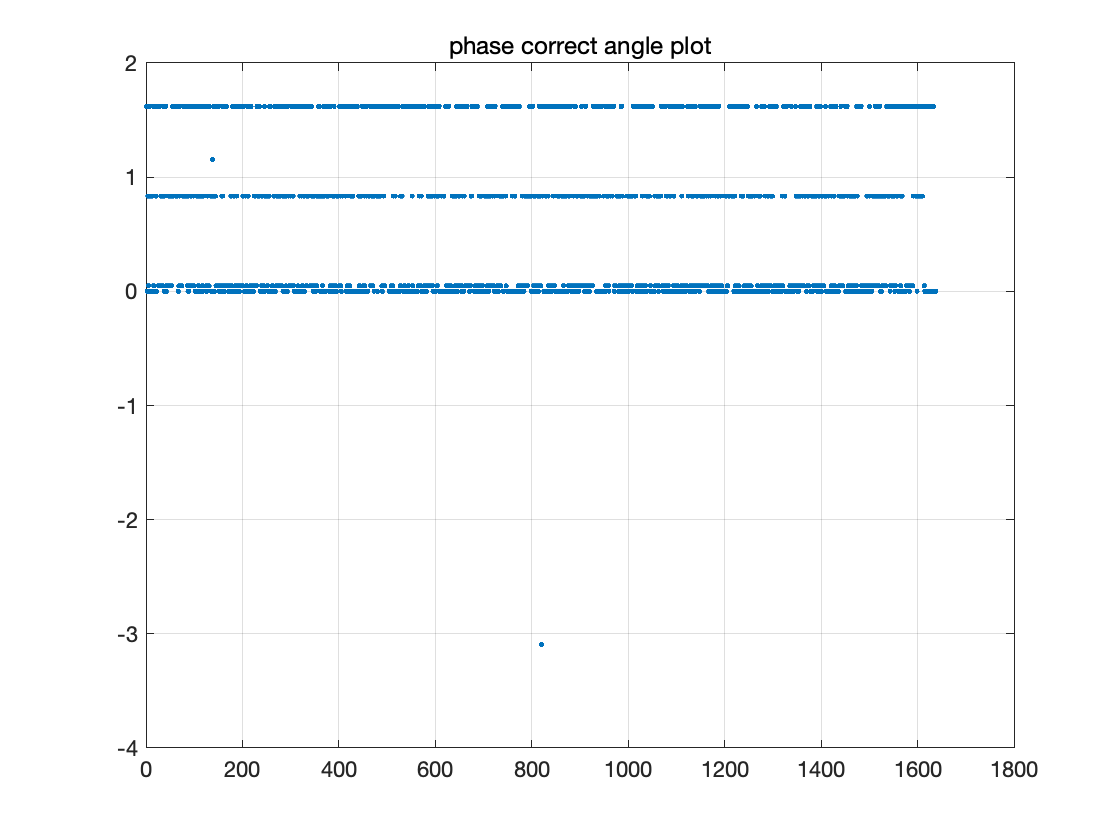

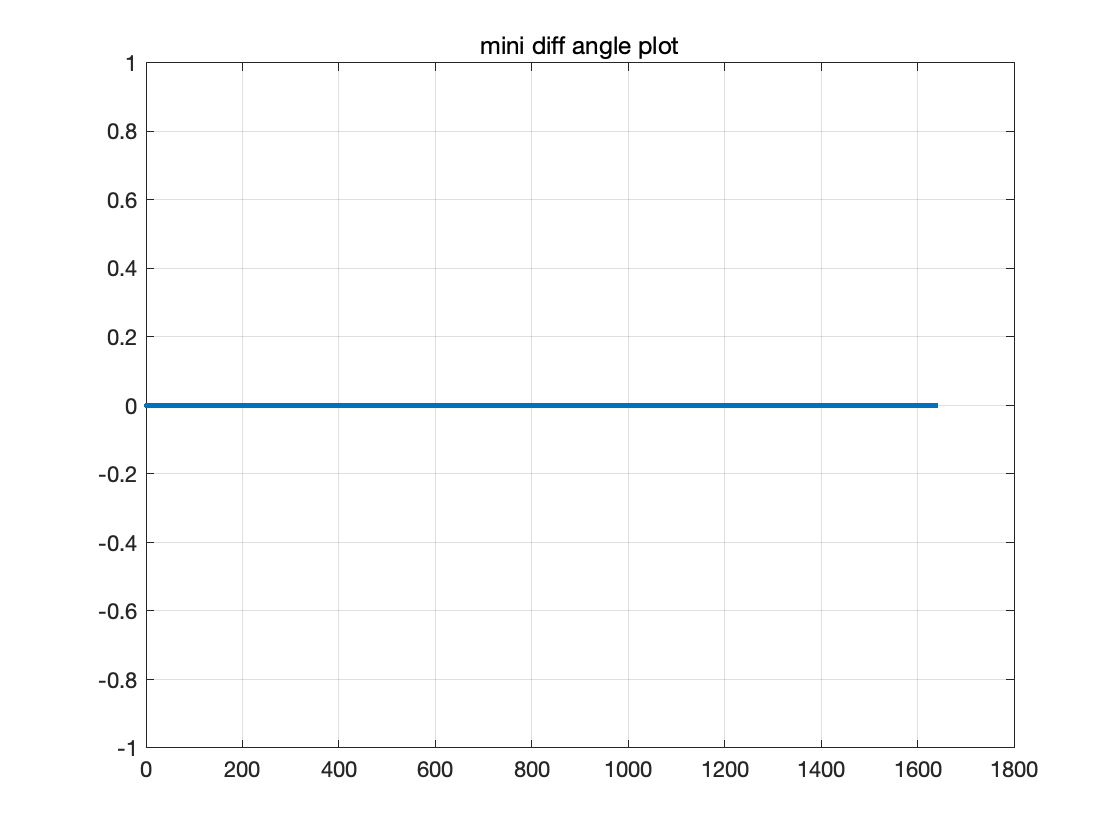

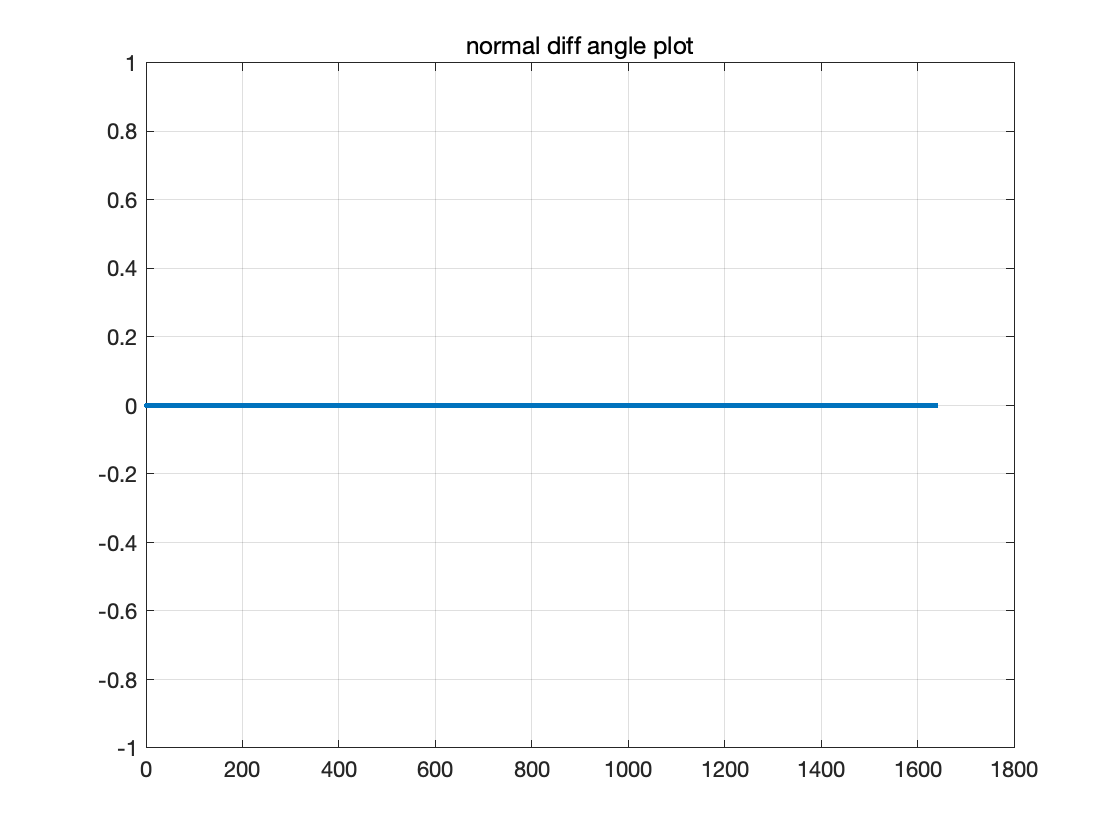

Decode port 1001 DMRS


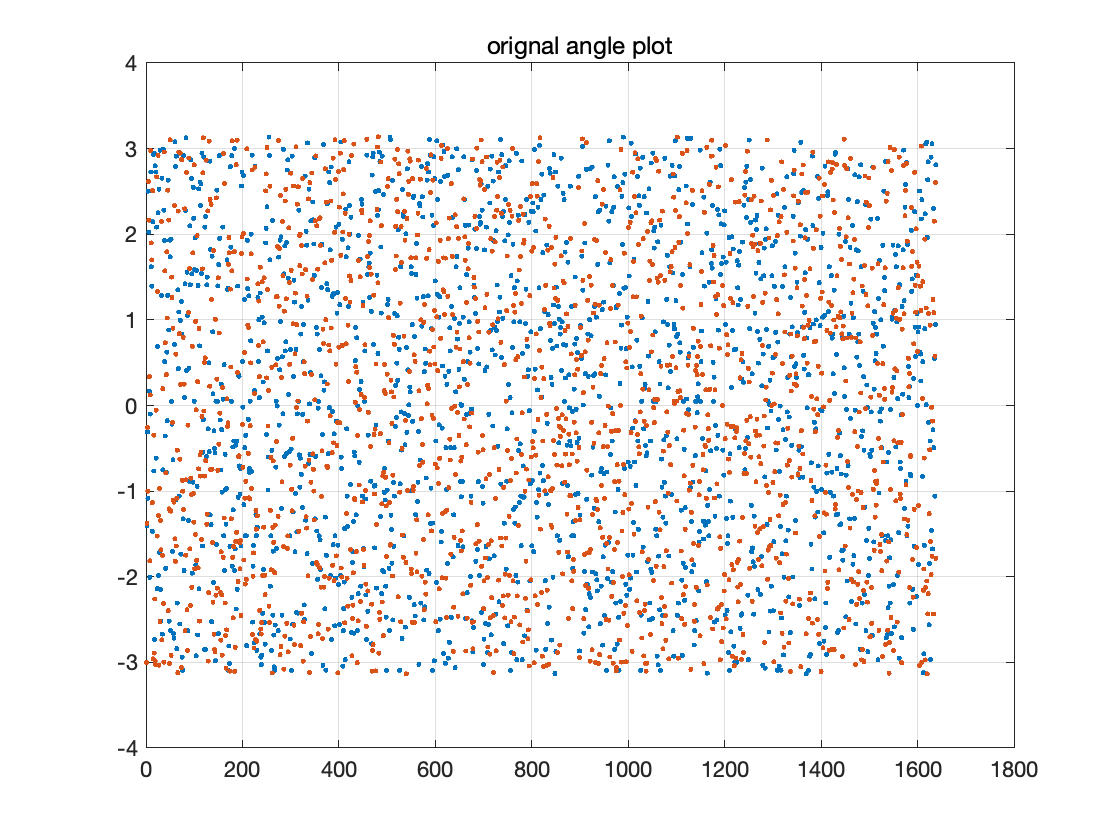

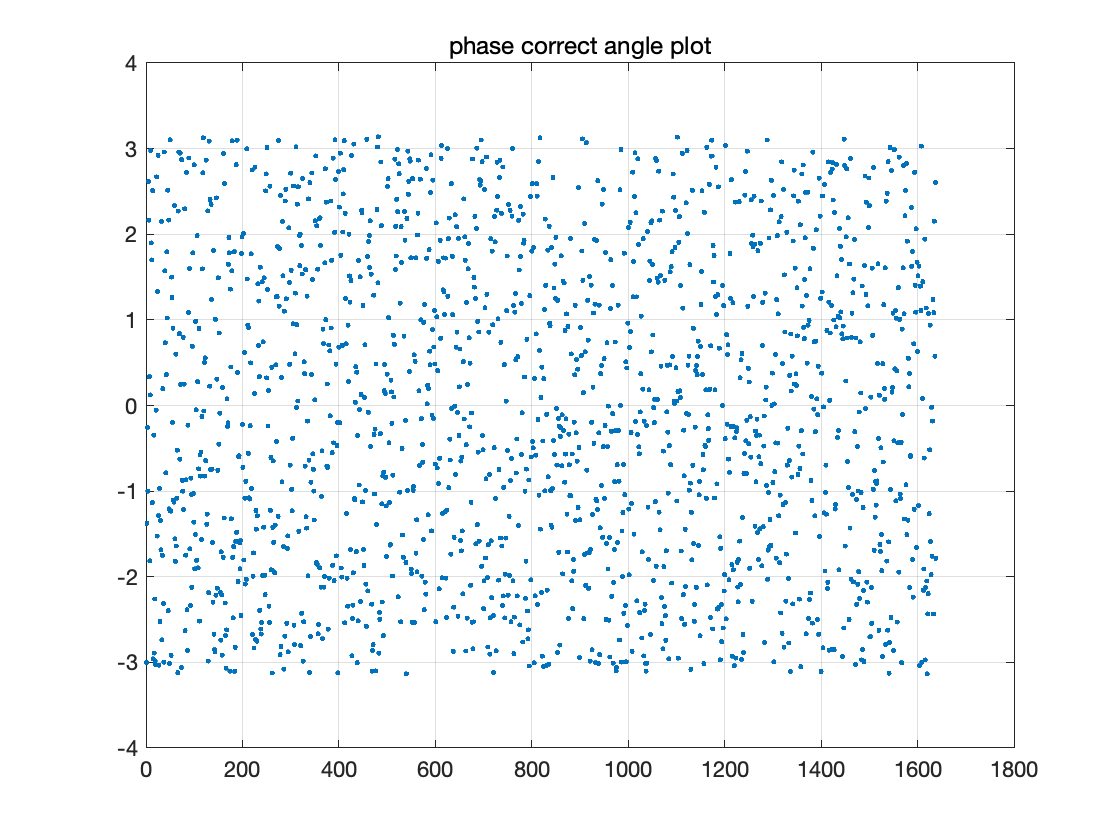

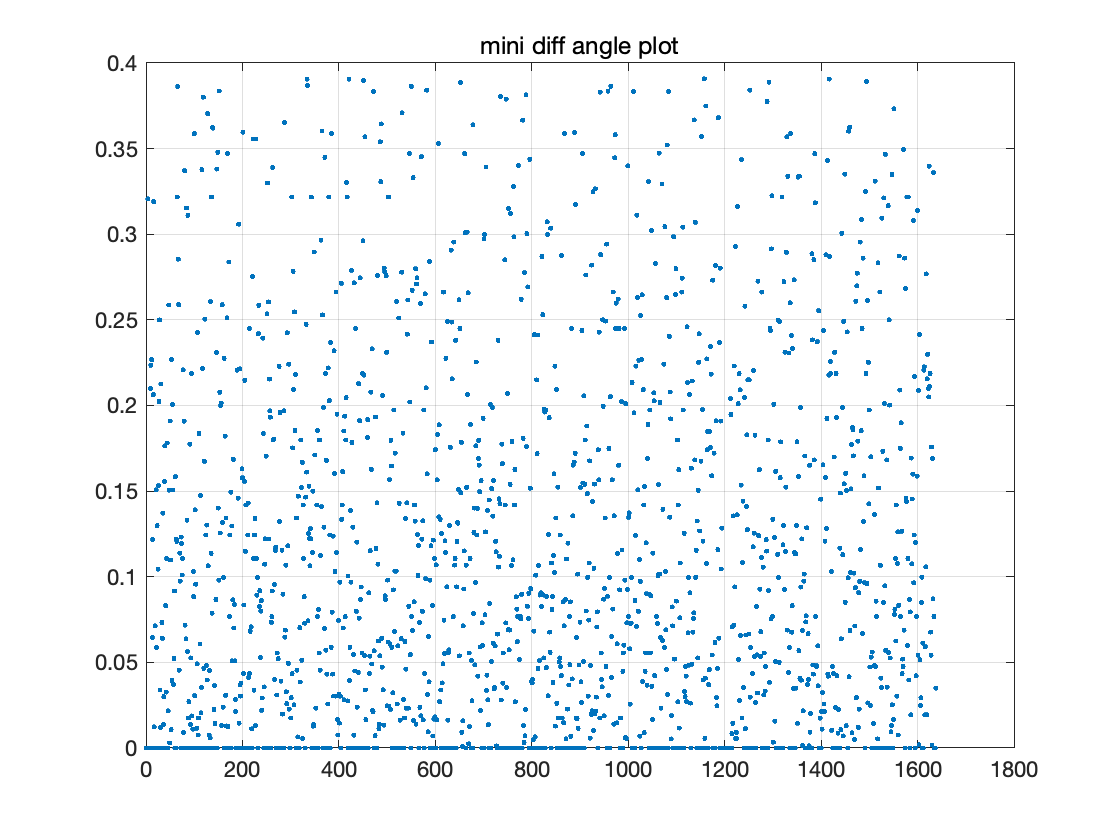

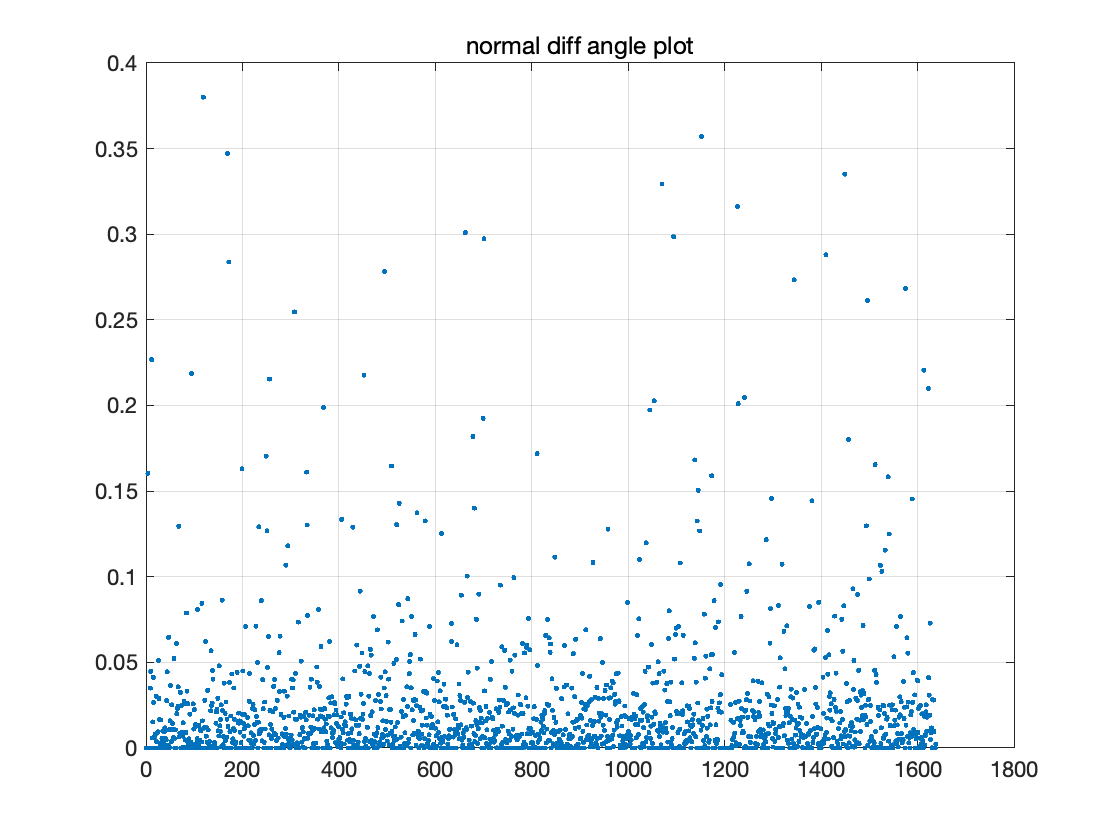

Decode port 1003 DMRS


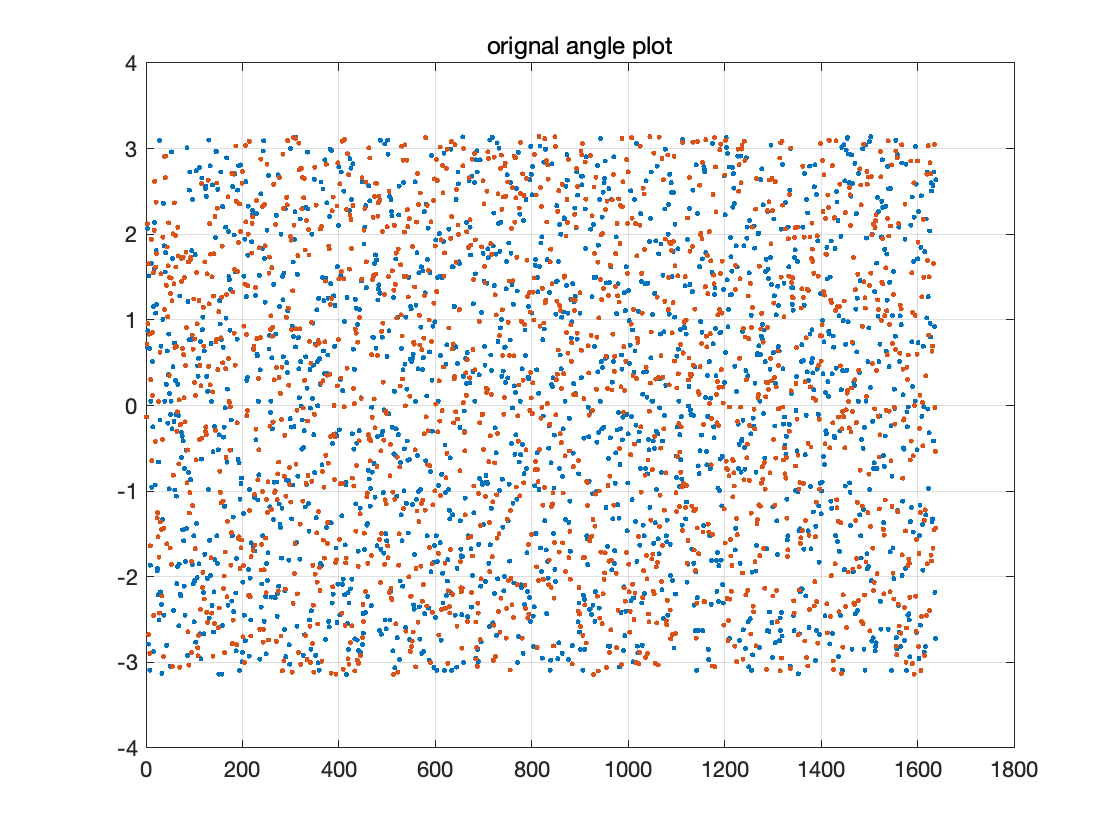

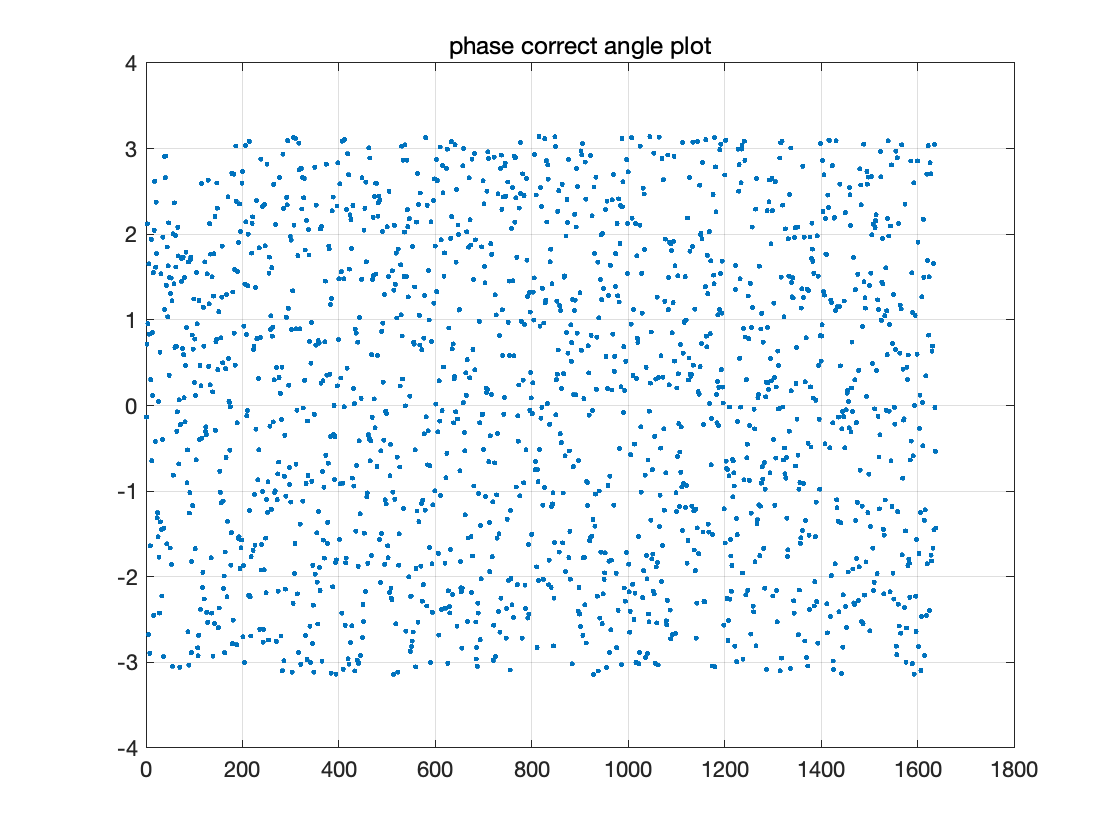

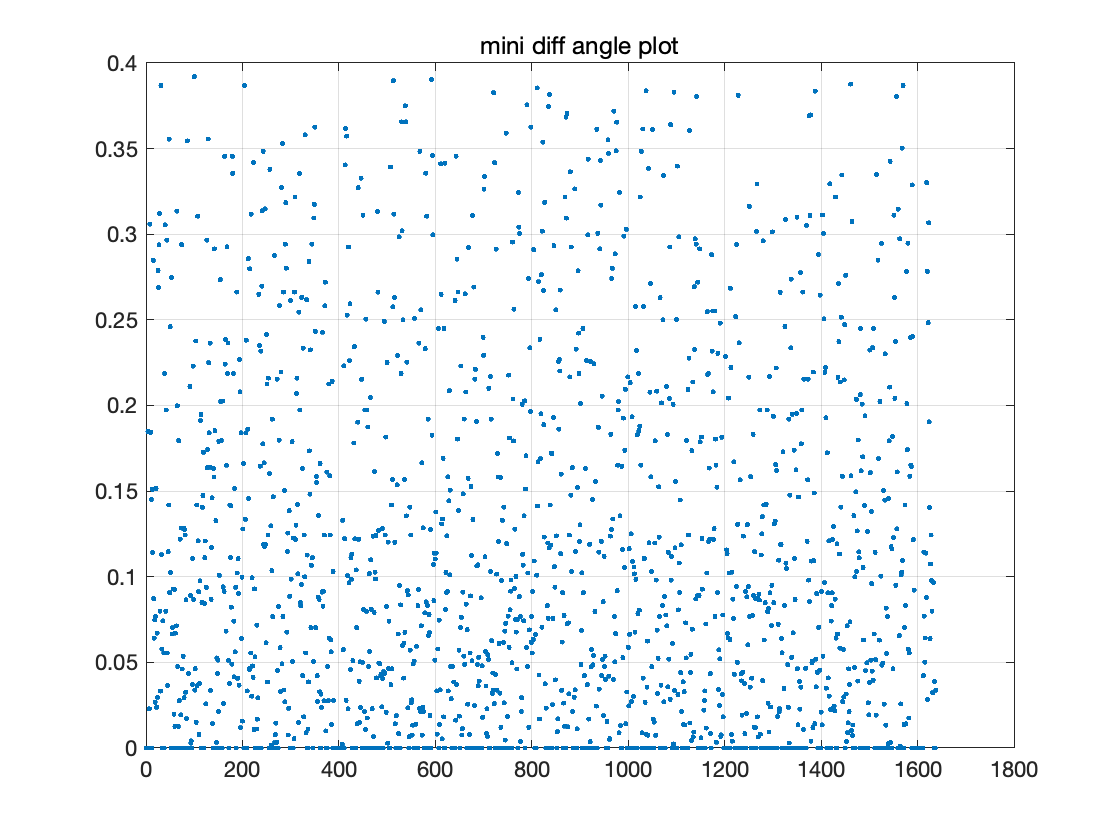

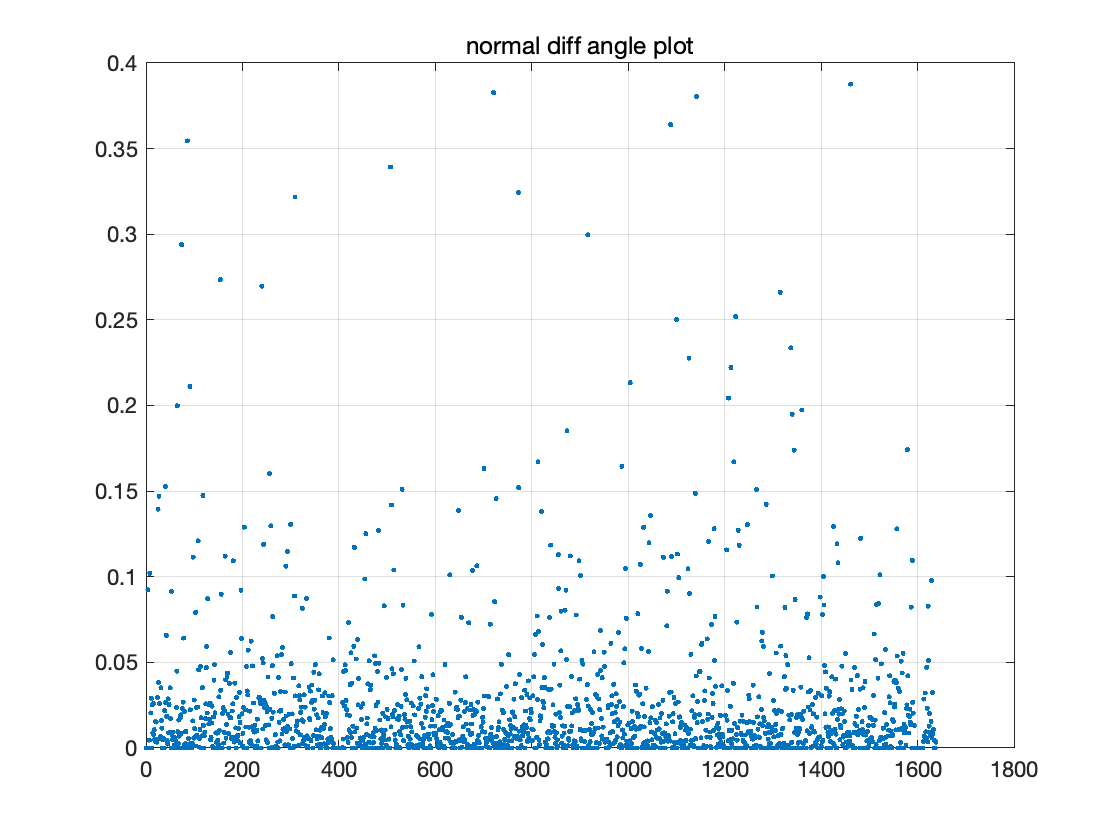

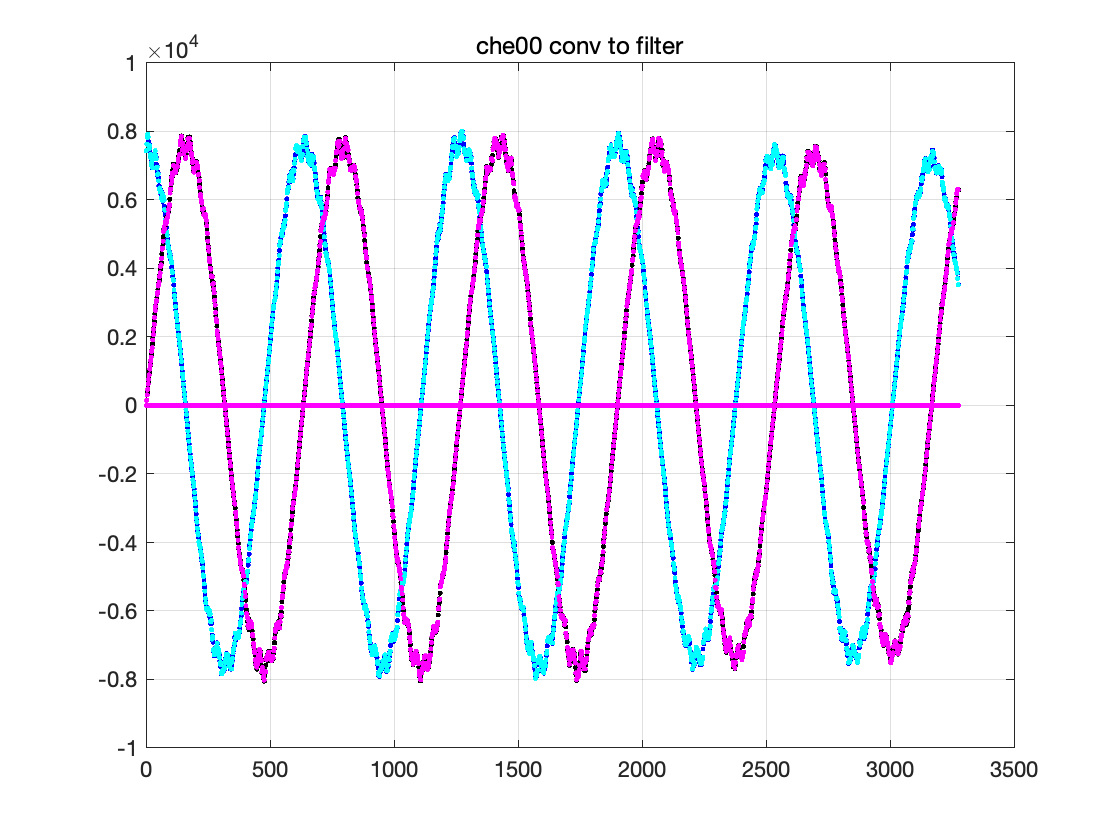

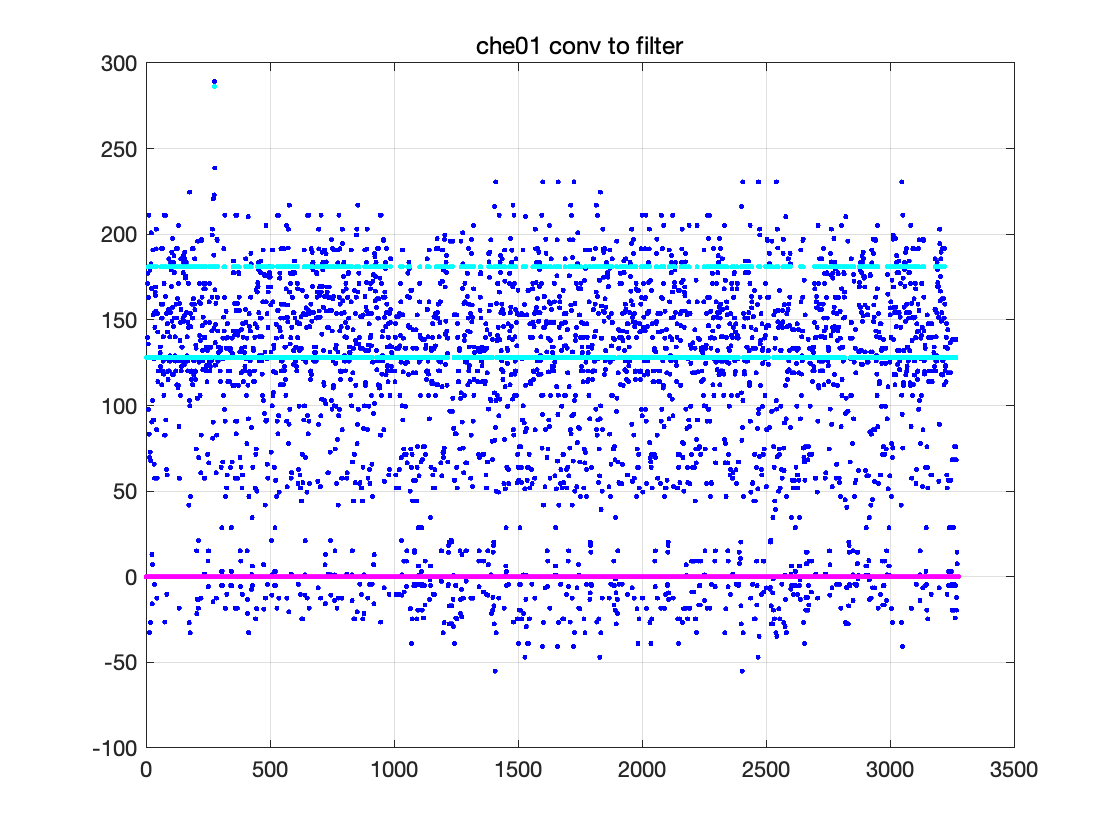

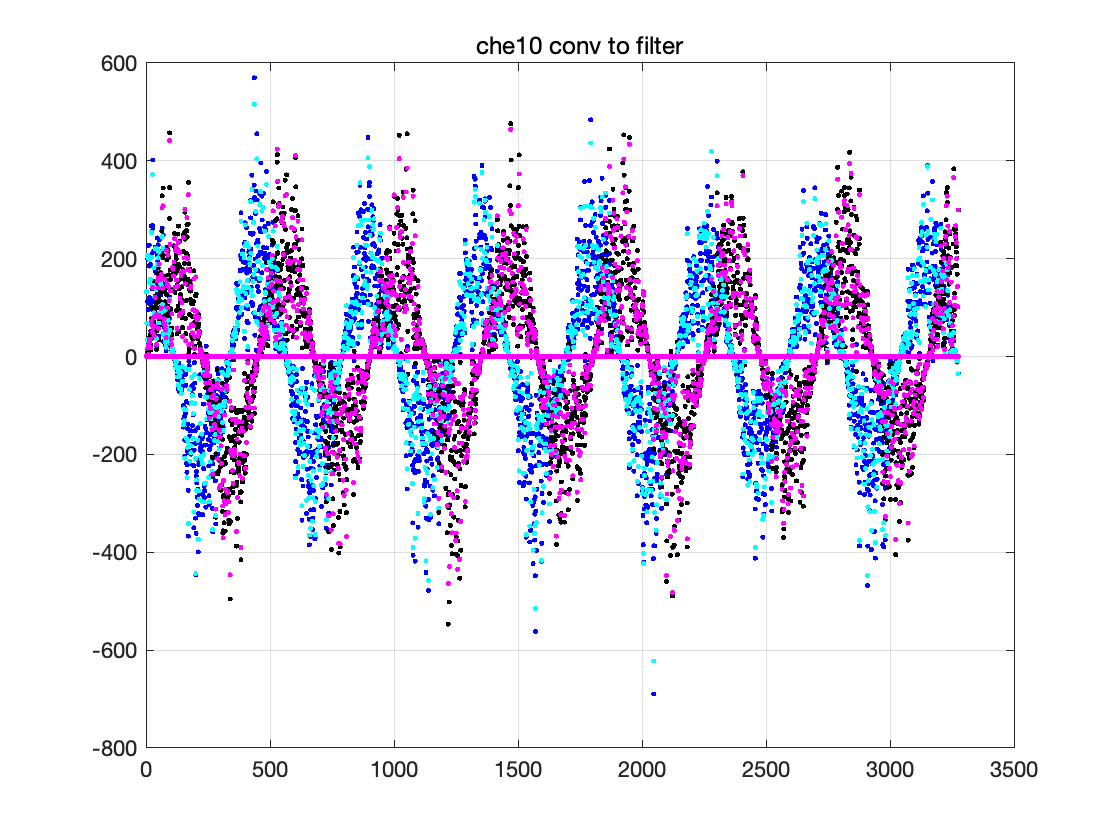

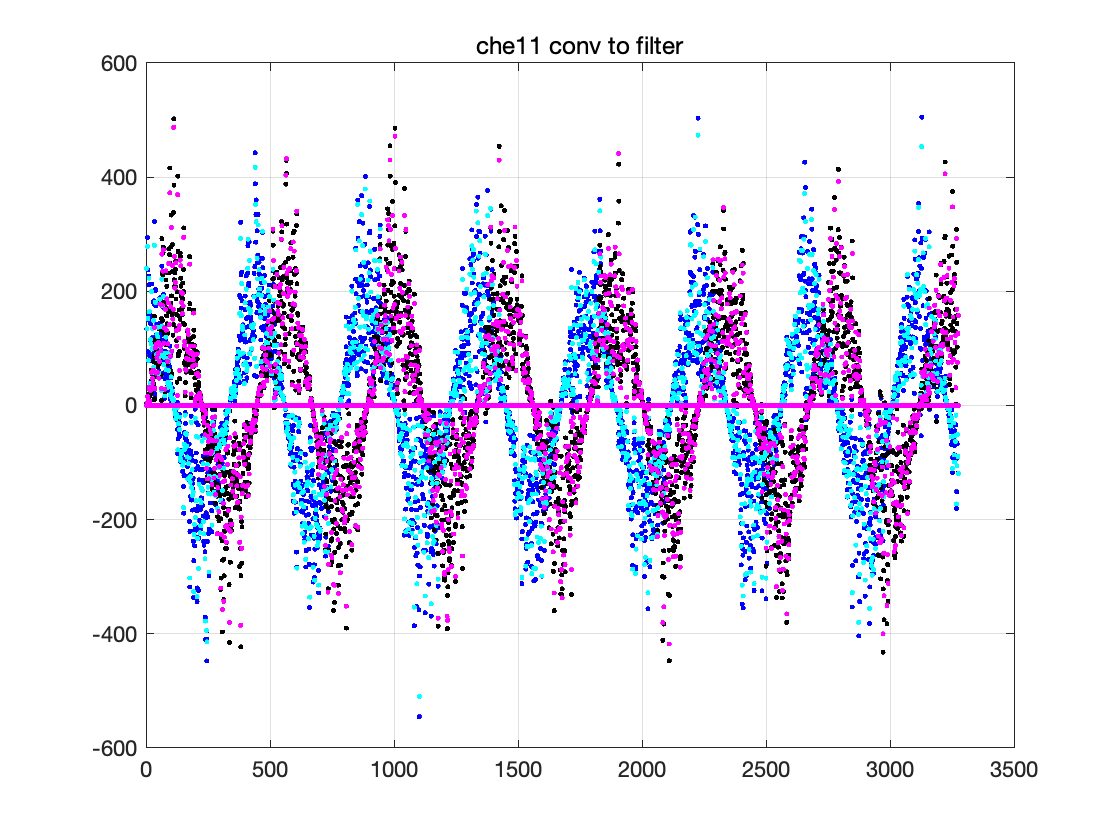

cpx0=Ant0_IQ(:,i+v_slot*14);
cpx1=Ant1_IQ(:,i+v_slot*14);
[che,cpx_che,cpx_pc]=CHEDMRS(cpx0,cpx1);

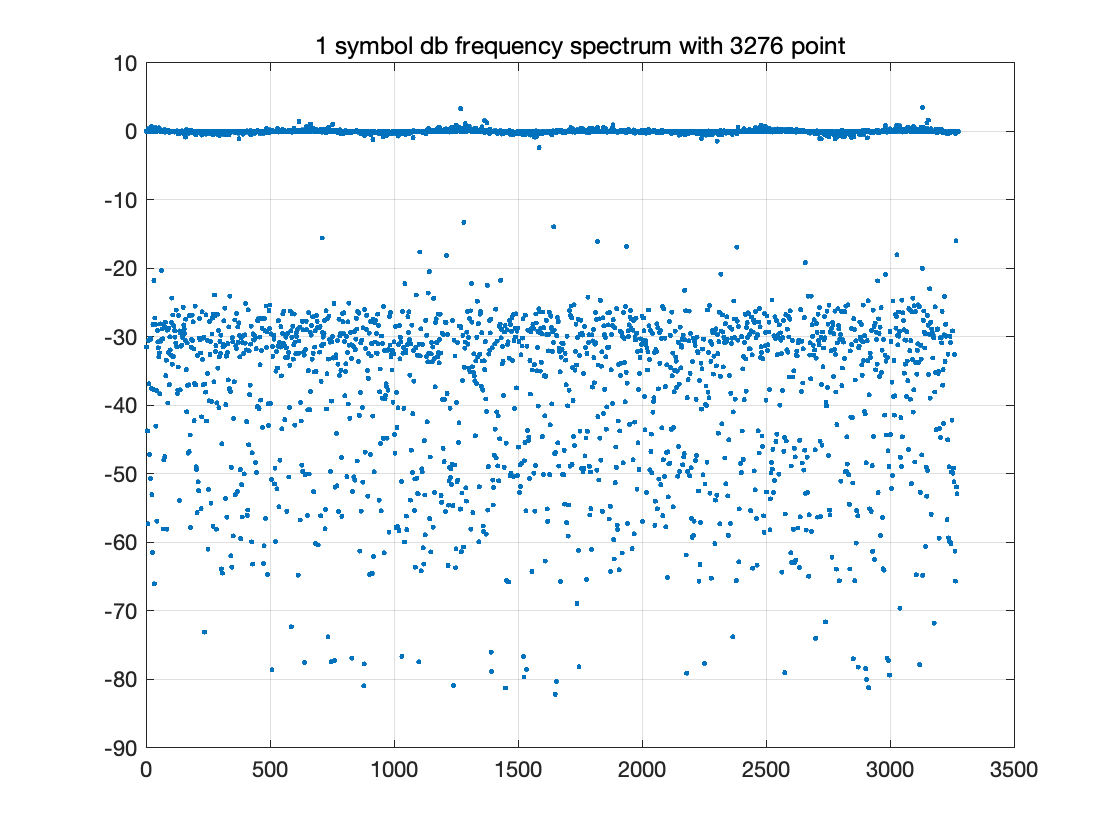

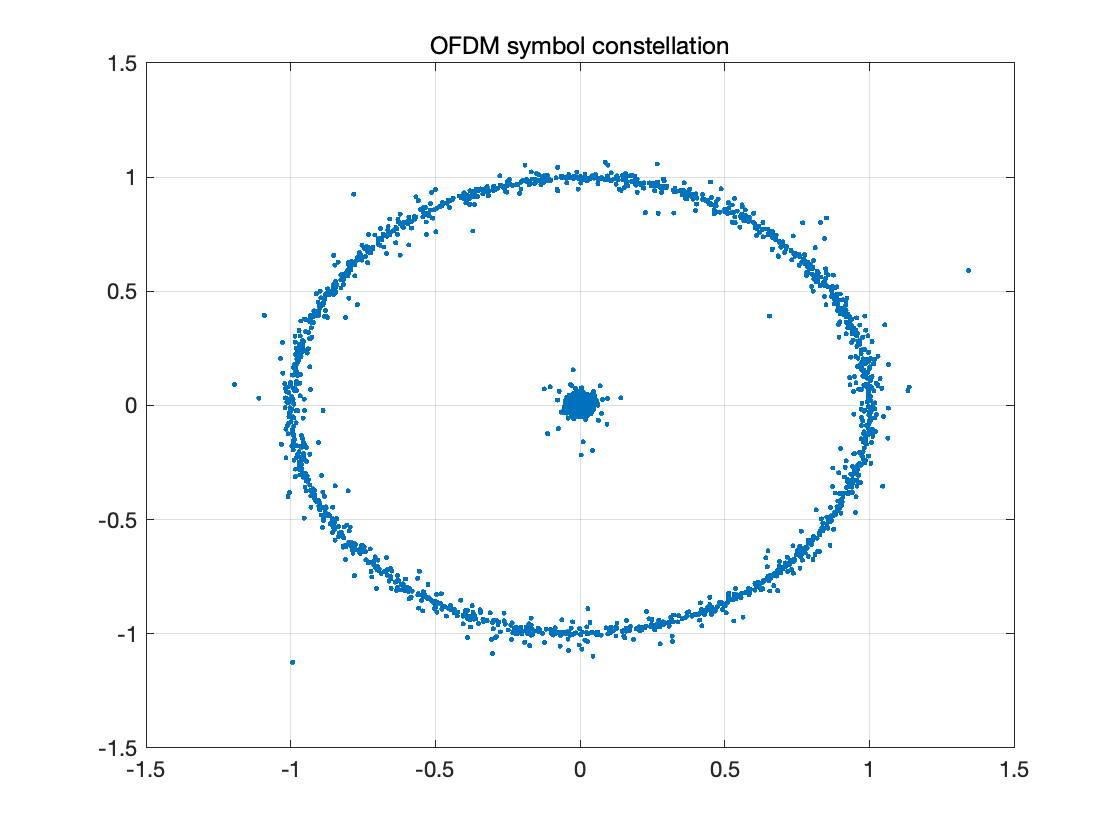

%[che,cpx_che,cpx_pc]
%Ant_view=Ant0_IQ;
plot1SymbolConstellation(cpx_che(:,1));

## total 28 symbol table out.

mu should be 1; conjugate should be 1 f0 is set to 26550000 Hz

## plot all data

for i=9:9
    plotConstellation(Ant0_IQ,i);
    plotConstellation(Ant1_IQ,i);
end

## plot dmrs

for i=9:9
    plotDMRS(Ant0_IQ,i);
    plotDMRS(Ant1_IQ,i);
end



%% plot full_slot

Ant_view1=reshape(Ant0_IQ,[],1);
Ant_view_abs=abs(Ant_view1);
base=max(Ant_view_abs);
log_freq=20*log10(Ant_view_abs./base);

figure;
plot(log_freq);
grid on;
str=sprintf('continuous OFDM symbol spectrum');
title(str);

seppoint=[15,15+14];
view_range=PlotSeqSpectrum(log_freq,seppoint);